%% Zmienne globalne
global g m c_w radius rho_s rho_p;

%% Wartości
g = 9.80665; % Przyspieszenie ziemskie [m/s^2]
m = 2; % Masa [kg]
c_w = 0.47; % Współczynnik oporu
radius = 0.0025;
rho_s = 1.2041; % Gęstość powietrza [kg/m^3]
rho_p = 20; % Gęstość styropianu [kg/m^3]

%% Stan początkowy i przedział czasu
wys_pocz = 20; % Początkowa wysokość [m]
start = [wys_pocz 0]; % [Początkowa wysokość, początkowa prędkość]
czas = [0 10];

%% Rozwiązanie równań różniczkowych
[t, A] = ode45(@Acceleration, czas, start);

% Obliczanie przyspieszenia na podstawie prędkości
a_t = diff(A(:,2)) ./ diff(t);

% Obliczenie momentu w czasie po któym kula spotka się z ziemią
% Znajdź indeks, dla którego prędkość jest najbliższa 0
[~, idx] = max(abs(A(:, 2)));

% Wyświetl czas, dla którego prędkość jest równa 0
fprintf('Czas, dla którego prędkość jest równa 0: %f s\n', t(idx));

Czas, dla którego prędkość jest równa 0: 7.597265 s


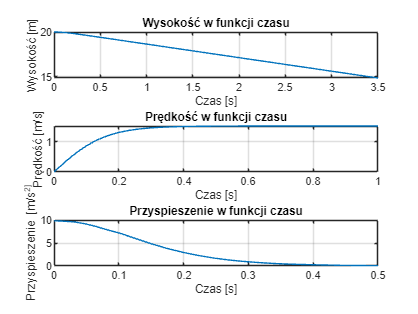


%% Wykresy
figure;
subplot(3, 1, 1);
plot(t, A(:, 1)), grid;
xlabel('Czas [s]'), ylabel('Wysokość [m]');
title('Wysokość w funkcji czasu');
xlim([0 3.5])

subplot(3, 1, 2);
plot(t, A(:, 2)), grid;
xlabel('Czas [s]'), ylabel('Prędkość [m/s]');
title('Prędkość w funkcji czasu');
xlim([0 1])

subplot(3, 1, 3);
plot(t(2:end), a_t), grid;
xlabel('Czas [s]'), ylabel('Przyspieszenie [m/s^2]');
title('Przyspieszenie w funkcji czasu');
xlim([0 0.5])

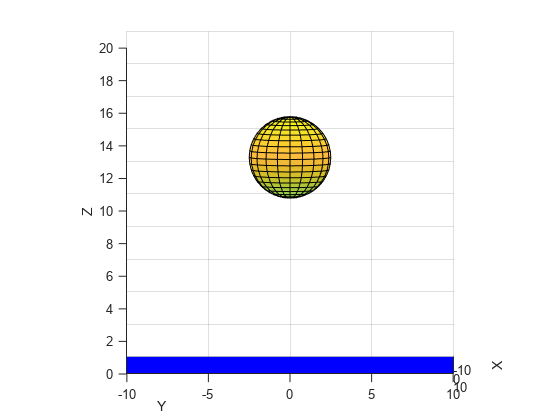


%% Tworzenie sceny
figure;
axis equal; % Ustawienie równej skali dla osiX, osiY i osiZ
axis([-10 10 -10 10 0 20]); % Ustawienie zakresu osi

hold on;
grid on;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
view([90 3]); % Widok 3D

% Tworzenie płaszczyzny
[X, Y] = meshgrid(-10:0.5:10, -10:0.5:10);
Z = zeros(size(X));
surface(X, Y, Z, 'FaceColor', 'b', 'EdgeColor', 'none');

% Tworzenie kuli
hSphere = createSphere(0, 0, wys_pocz+radius, radius*1000);

% Animacja spadku kulki
for i = 1:length(find(A(:, 1)>=0))
    zData = get(hSphere, 'ZData');
    set(hSphere, 'ZData', zData + (A(i, 1) - A(1, 1)));

    

    drawnow limitrate;
    pause(0.01)

    % Sprawdź warunek kolizji
    if zData <= radius
        % Zatrzymaj kulkę na płaszczyźnie
        set(hSphere, 'ZData', zData+radius*1000);
        break; % Wyjdź z pętli
    end
end

## Funkcja przyspieszenie (spadek kuli)

function dv = Acceleration(~, hv)
    global g m c_w radius A rho_s rho_p;
    
    v = hv(2); % Prędkość, dodatnia w dół
    m = (4/3)*pi*radius^3*rho_p; % Masa kulki [kg]
    A = pi*radius^2; % Powierzchnia przekroju [m^2]

    % Obliczenie przyspieszenia
    dh_dt = -v; % dh/dt
    dv_dt = g - (1/(2*m))*c_w*A*rho_s*v^2; % dv/dt
    
    dv = [dh_dt; dv_dt];
end